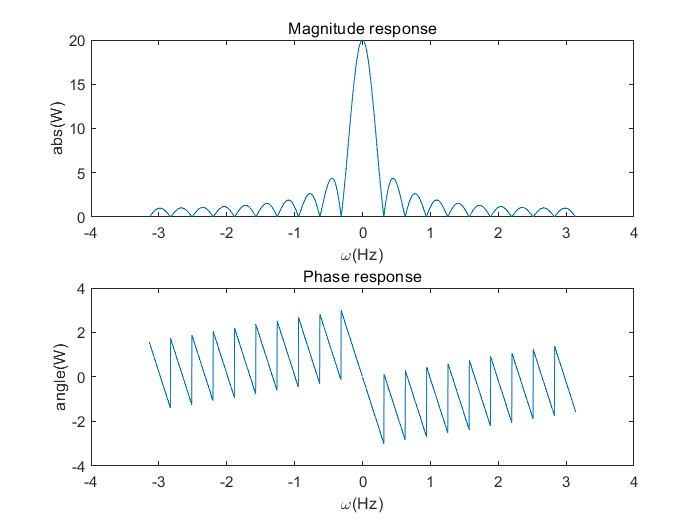

%q1
close all;clear;
N=20;
w=-pi:pi/1000:pi;
W = (w~=0).*exp(-1j*w*(N-1)/2).*sin(w*N/2)./(sin(w/2))+(w == 0)*N;
subplot(211),plot(w,abs(W)),xlabel('\omega(Hz)'),ylabel('abs(W)'),title('Magnitude response');
subplot(212),plot(w,angle(W)),xlabel('\omega(Hz)'),ylabel('angle(W)'),title('Phase response');

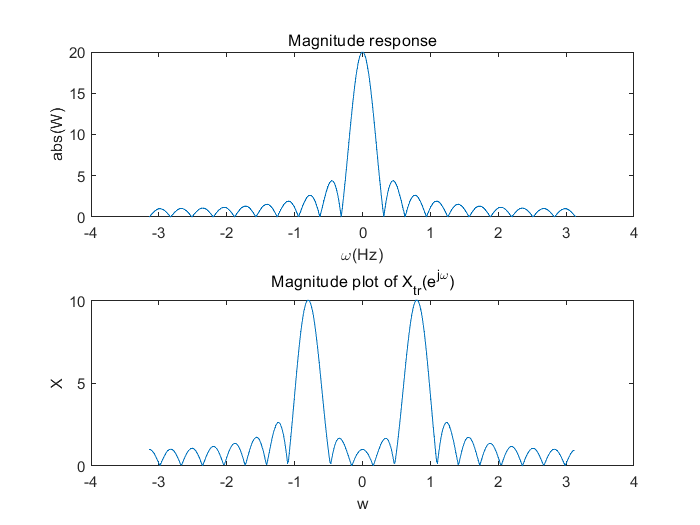


%q2
% Truncate the signal
clear;
n=0:19;
x=cos(pi/4*n);
[X,w]=DTFT(x,512);
plot(w,abs(X)),xlabel('w'),ylabel('X'),title('Magnitude plot of X_{tr}(e^{j\omega})');